# Examples Notebook

This notebook is going to be used to create the graphics for alot of the images used in chapter 2 of my thesis. The first two are going to be the correlation example and the TFD examples.

## Correlations

% --Setup
    clear; clc; format compact; close all; warning off;

% --Declare Basic Signal

    % --Signal Parameters
        T = 1;              % Signal Period T (s)
        fs = 10000;         % Sample Rate (Hz)
        t = 0:1/fs:T;
        f = 10*2*pi;        % Frequency (Hz)

    % --Create signal
        amplitude = 0.25;
        envelope = amplitude.* sin(pi*t);
        ref_signal = envelope .* sin(f*t);

% --Creating sample signal
    t1 = 0:1/fs:5;
    amplitude = 0.25;
    envelope = amplitude.* sin(pi*t);
    signal = envelope .* sin(f*t);
    signal = [signal, zeros(1, 2*fs), signal, zeros(1, 1*fs - 1)];
    noise = randi(100,1,length(signal))./500;
    noisy_signal = noise + signal;
    signal = noisy_signal - mean(noisy_signal);

% --Zero pad signals to make same length
    diff = length(signal) - length(ref_signal);
    pad = zeros([1, diff]);
    ref_signal_long = [ref_signal, pad];

% --Compute SNR values
    noise_power = sum(noise.^2)/(2*length(noise) + 1);
    signal_power = sum(ref_signal.^2)/(2*length(ref_signal) + 1);
    SNR = 10*log10(signal_power/noise_power);
    fprintf('SNR for this data set is %3.3f',SNR)

SNR for this data set is 0.603

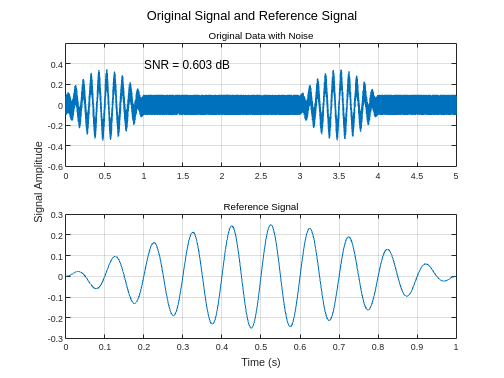

    asdf = sprintf('SNR = %3.3f dB',SNR);
    
% --Plot original Signals
    fig = figure();
    subplot(2,1,1)
    plot(t1, signal)
        hold on
        grid on
        subtitle("Original Data with Noise")
        sgtitle("Original Signal and Reference Signal")
        text(1, 0.4, asdf, "FontSize",12)
        ylim([-0.6 0.6])

    subplot(2,1,2)
    plot(t, ref_signal)
        hold on
        grid on
        subtitle('Reference Signal')

        % --Give common xlabel, ylabel and title to your figure
            han=axes(fig,'visible','off'); 
            han.Title.Visible='on';
            han.XLabel.Visible='on';
            han.YLabel.Visible='on';
            ylabel(han,'Signal Amplitude');
            xlabel(han,'Time (s)')

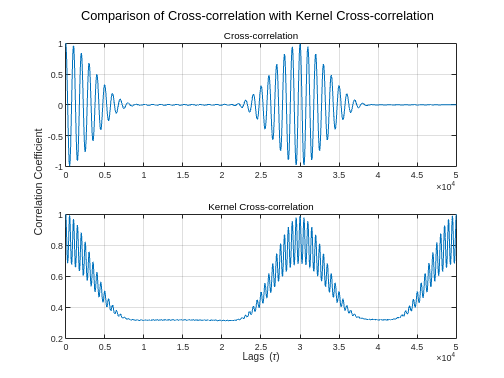

% --Find DFT of signals
    f_signal = fft(signal);
    f_ref_sig = fft(ref_signal_long);

% --Find corr
    corr = f_signal .* conj(f_ref_sig);
    corr = ifft(corr);
    corr = corr - min(corr);
    corr = corr ./ max(corr);

% --calling xcorr functiont τ = 0
    corr2 = xcorr(signal, ref_signal);
    corr2 = corr2(length(signal):2*length(signal) -1 );
    corr2 = corr2 ./ max(corr2);

% --kxcorr 
    k_signal = abs(signal + signal);
    k_ref_signal = abs(ref_signal_long + ref_signal_long);

    f_k_signal = fft(k_signal);
    f_k_ref_signal = fft(k_ref_signal);

    output = ifft(f_k_signal .* conj(f_k_ref_signal));
    output = output ./ max(output);

% --Plot correlation
    fig = figure();
    subplot(2,1,1)
    plot(corr2)
        hold on
        grid on
        xlim([0 length(signal)])
        subtitle('Cross-correlation')

    subplot(2,1,2)
    plot(output)
        hold on
        grid on
        xlim([0 50001])
        xlabel("Lags (\tau)")
        subtitle('Kernel Cross-correlation')
        sgtitle("   Comparison of Cross-correlation with Kernel Cross-correlation")

        % --Give common xlabel, ylabel and title to your figure
            han=axes(fig,'visible','off'); 
            han.Title.Visible='on';
            han.XLabel.Visible='on';
            han.YLabel.Visible='on';
            ylabel(han,'Correlation Coefficient');

## Autocorrelation Examples

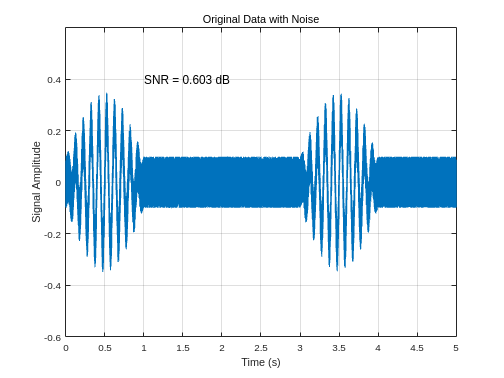

% --Autocorrelation of the noisy signal
    [auto_corr, lags] = xcorr(noisy_signal,"biased");
    auto_corr = auto_corr ./ max(auto_corr);
    
% --Plot
    figure()
    plot(t1, signal)
        hold on
        grid on
        subtitle("Original Data with Noise")
        sgtitle("")
        text(1, 0.4, asdf, "FontSize",12)
        ylim([-0.6 0.6])
        ylabel("Signal Amplitude")
        xlabel("Time (s)")

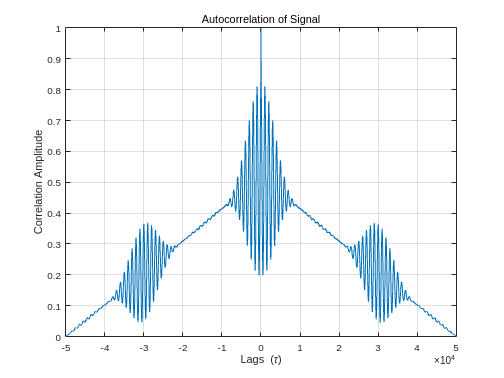

    figure()
    plot(lags, auto_corr)
        grid on
        hold on
        xlim([-50000 50000])
        xlabel('Lags (\tau)')
        subtitle("Autocorrelation of Signal")
        ylabel("Correlation Amplitude")

## Spectrograms and TFD

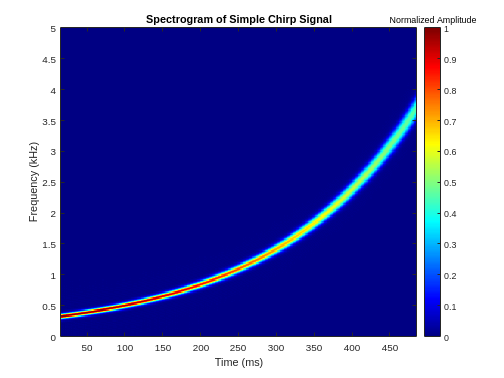

% --Create Chirps
    figure()
    chirp = create_chirp("logarithmic", 1, 0.5, 300, 4000, 10000, "true");
    title("Spectrogram of Simple Chirp Signal")

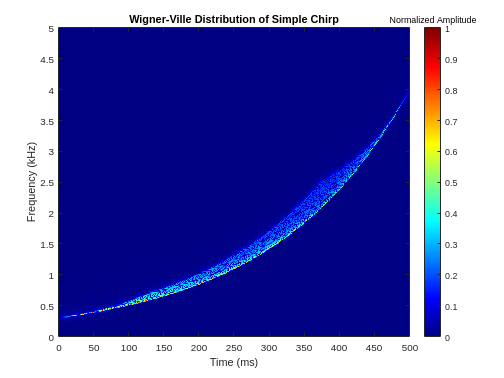

% --Find WVD of chirp
    [s, f, t] = wvd(chirp, 10000);
        s = abs(s);
        s = s - min(min(s));
        s = s ./ max(max(s));
        t = t .* 1000;
        f = f ./ 1000;

% --Make image
    figure()
    imagesc(t,f,s)
        set(gca,"YDir","normal")
        colormap('jet')
        clb = colorbar;
        title('Unfiltered Spectrogram of Data')
        xlabel('Time (ms)');
        ylabel('Frequency (kHz)')
        clb.Title.String = "Normalized Amplitude";
        maxf = max(max(f));
        minf = min(min(f));
        ylim([minf maxf])
        xlim([0 500])
        title("Wigner-Ville Distribution of Simple Chirp")